## Señal modulada 4QAM

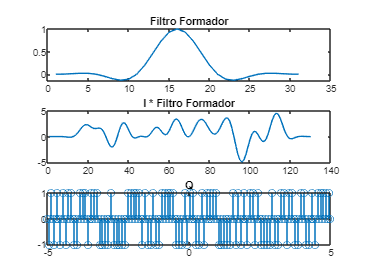

%% Manejo de Bits (Q & I)
figure(1)
S = 100;
BpS = 2;
Bits = 2*(round(rand(1, BpS*S)) - 0.5);
stem(Bits)
title('Bits');
I = zeros(1, S);
Q = zeros(1, S);
j = 1;
for i = 1 : S*BpS
    if(mod(i,2))
        I(j) = Bits(i);
    else
        Q(j) = Bits(i);
        j = j + 1;
    end
end
f = 10;
tc = -5 : 1/(2*f) : 5;

Idis = zeros(1, length(tc));
Qdis = zeros(1, length(tc));

cero = find(tc == 0);

Idis(cero - 10*f + 1 : 2 : cero + 10*f - 1) = I;
Qdis(cero - 10*f + 1 : 2 : cero + 10*f - 1) = Q;

stem(tc, Idis)
title('I');

stem(tc, Qdis)
title('Q');

## Filtro formador Coseno Elevado

% 1 simbolo por segundo

% Multiplicacion señal modulada amplitud
% portadora 25 Hz
%% Filtro Formador
figure(2)
filfor = rcosine(1,5);

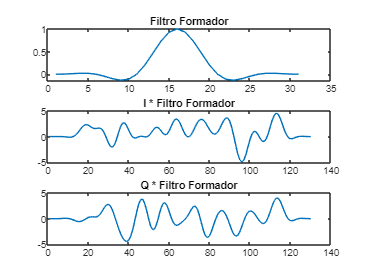

plot(filfor);
title('Filtro Formador');

Ifilfor = conv(I, filfor);
Qfilfor = conv(Q, filfor);

plot(Ifilfor);
title('I * Filtro Formador');

plot(Qfilfor);
title('Q * Filtro Formador');

%% Modulación
figure(3)
tr = (length(Qfilfor)/2)/f;
t = -tr : 1/f : tr - 1/f;
A = 1;

portI = A*cos(2*pi*f*t);
portQ = A*-cos(2*pi*f*t);

Imod = Ifilfor.*portI;
Qmod = Qfilfor.*portQ;

plot(t, Imod);
title('Portadora X I*F');

plot(t, Qmod);
title('Portadora X Q*F');

mod4QAM = Imod + Qmod;

plot(t, mod4QAM);
title('4QAM');

## Demodulacion Coherente 4QAM

% multiplicacion y filtrado
% corrimiento de pase portadora pi/4, pi/2, 3pi/4 y pi
% desviacion frecuencia .1Hz
% observaciones
%% Demodulación
filpb = zeros(1, length(mod4QAM));

filpb(find(filpb <= f) : find(filpb >= -f)) = 1;

Ires = mod4QAM.*portI;

Qres = mod4QAM.*portQ;

Iresf = ifftshift(Ires);
Iresf = fft(Iresf);
Iresf = fftshift(Iresf);

Ifilpbf = Iresf.*filpb;

Ifilpb = ifftshift(Ifilpbf);
Ifilpb = fft(Ifilpb);
Ifilpb = fftshift(Ifilpb);

Qresf = ifftshift(Qres);
Qresf = fft(Qresf);
Qresf = fftshift(Qresf);

Qfilpbf = Qresf.*filpb;

Qfilpb = ifftshift(Qfilpbf);
Qfilpb = fft(Qfilpb);
Qfilpb = fftshift(Qfilpb);

## Filtro Pasa bajas

## Muestreo y Normalizacion Simbolos

% Grafica de Constelaciones
% Usar scatterplot.m
% Comparacion señal transmitida
    % Multiplicar señal cuadratura por j 
    % sumar a la señal en fase antes usar scatterplot.m
    